# Plot a group averaged ERP from the command line

You will need to download the data first. If you have not downloaded the data, go to this [page](https://eeglab.org/tutorials/tutorial_data.html).

#### Load existing study from sample_data eeglab folder:

eeglab; close;

Some menus items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m


Retrieving plugin versions from server...
Retreiving download statistics...
EEGLAB: adding "Fileio" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "HEDTools" v2.7.0 (see >> help eegplugin_hedtools)


EEGLAB: adding "ICLabel" v1.3 (see >> help eegplugin_iclabel)
EEGLAB: adding "PICARD" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "PrepPipeline" v0.55.4 (see >> help eegplugin_prepPipeline)


EEGLAB: adding "bids-matlab-tools" v5.2 (see >> help eegplugin_bids)
EEGLAB: adding "bids-validator" v1.1 (see >> help eegplugin_bidsvalidator)


EEGLAB: adding "bva-io" v1.7 (see >> help eegplugin_bva_io)


EEGLAB: adding "clean_rawdata" v2.3 (see >> help eegplugin_clean_rawdata)


EEGLAB: adding "corrmap" v2.1 (see >> help eegplugin_corrmap)


EEGLAB: adding "dipfit" v3.6 (see >> help eegplugin_dipfit)


EEGLAB: adding "erpsource" v1.0 (see >> help eegplugin_erpsource)
EEGLAB: adding "fieldtrip-" to the path; subfolders (if any) might be missing from the path


EEGLAB: adding "finderscourse" v1.1 (see >> help eegplugin_finderscourse)


EEGLAB: adding "firfilt" v2.4 (see >> help eegplugin_firfilt)


EEGLAB: adding "iirfilt" v1.03 (see >> help eegplugin_iirfilt)


EEGLAB: adding "lsl_app_matlabviewer" v1.0 (see >> help eegplugin_lsl_app_matlabviewer)


EEGLAB: adding "mffmatlabio" v3.5 (see >> help eegplugin_mffmatlabio)


EEGLAB: adding "mp_clustering" v2.0 (see >> help eegplugin_mp_clustering)


EEGLAB: adding "neuroscanio" v1.4 (see >> help eegplugin_neuroscanio)


EEGLAB: adding "nsgportal" v2.0 (see >> help eegplugin_nsgportal)


EEGLAB: adding "relica" v1.0 (see >> help eegplugin_RELICA)


EEGLAB: adding "roiconnect" v1.0 (see >> help eegplugin_roiconnect)


EEGLAB: adding "snapmaster" v1.0 (see >> help eegplugin_snapmaster)


EEGLAB: adding "xdfimport" v1.16 (see >> help eegplugin_xdfimport)


You are using the latest version of EEGLAB.


if ~exist('n400.study', 'file')
    warndlg2([ 'Now select the n400.study file. Download the data from' 10 ...
        'https://eeglab.org/tutorials/tutorial_data.html (5 subject study)' ]);
    [STUDY, ALLEEG] = pop_loadstudy;
else
    cd(fileparts(which('n400.study')));
    [STUDY, ALLEEG] = pop_loadstudy(fullfile(pwd, 'n400.study'));
end


pop_loadset(): loading file ./s02/syn02-s253-clean.set ...
pop_loadset(): loading file ./s05/syn05-s253-clean.set ...
pop_loadset(): loading file ./s07/syn07-s253-clean.set ...
pop_loadset(): loading file ./s08/syn08-s253-clean.set ...
pop_loadset(): loading file ./s10/syn10-s253-clean.set ...
pop_loadset(): loading file ./s02/syn02-s254-clean.set ...
pop_loadset(): loading file ./s05/syn05-s254-clean.set ...
pop_loadset(): loading file ./s07/syn07-s254-clean.set ...
pop_loadset(): loading file ./s08/syn08-s254-clean.set ...
pop_loadset(): loading file ./s10/syn10-s254-clean.set ...


#### Compute ERP measure for the STUDY set

[STUDY ALLEEG] = std_precomp(STUDY, ALLEEG, {},'savetrials','on', ...
'interp','on',... % interpolate missing channels
'recompute','on',... % recompute measure if already present
'erp','on',... % compute ERPs
'erpparams',{'rmbase' [-300 0] }); %specify ERP baseline

Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing baseline...
Saving ERP file './s02/S02.daterp'
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
eeg_checkset: recomputing the ICA activation matrix ...
Removing baseline...
Saving ERP file './s05/S05.daterp'
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing baseline...
Saving ERP file './s07/S07.daterp'
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activation matrix ...
Removing baseline...
Saving ERP file './s08/S08.daterp'
Scaling components to RMS microvolt
eeg_checkset: recomputing the ICA activa

#### Specify statistical parameters

STUDY  = pop_statparams(STUDY,... 
'condstats','on',... % perform stats on 1st independant variable
'method','perm',... % use perumtation method
'mcorrect','fdr',...% correct for multiple comparisons using fdr
'alpha',0.01); %specify statistical threshold


### **Plot ERP time course**

When calling the function std_erplots, we specify erpdata and erptimes to retrieve these measures from the outputs:

- erpdata is the ERP data for each condition, group and subject. It is a cell array of size [nconds x ngroups], each element is of size [times x subjects] for data channels.

- erptimes is an array of the ERP time points latencies

Specify the ERP time range to plot:

timerange_min =-300

timerange_min = -300

timerange_max =1320

timerange_max = 1320

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


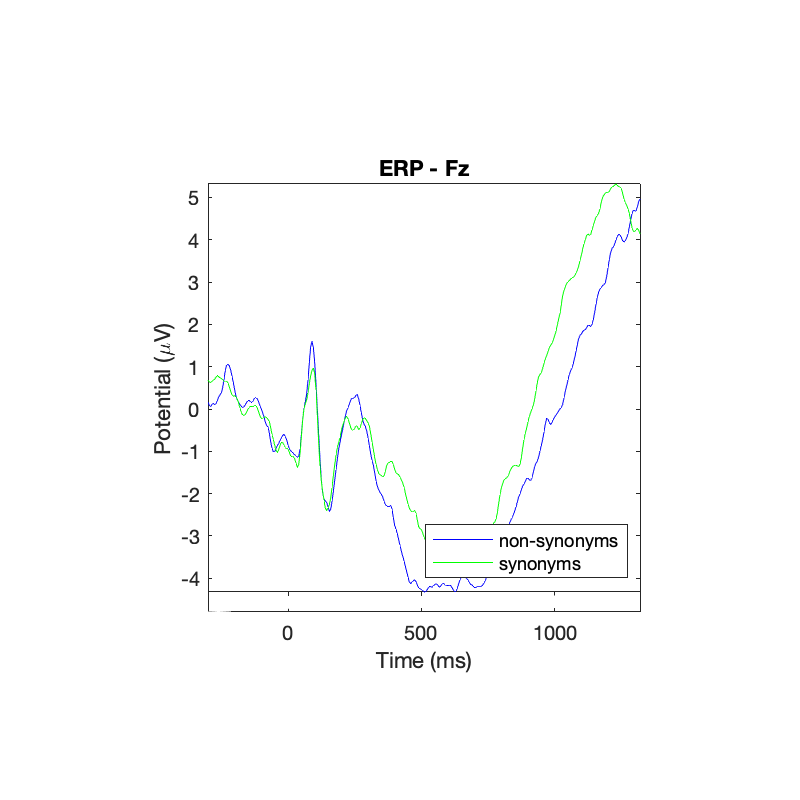


STUDY = pop_erpparams(STUDY, 'plotconditions','together'); % specify plot parameters
[STUDY erpdata erptimes] = std_erpplot(STUDY,ALLEEG,'channels',{'Fz'}, 'design', 1, 'timerange',[timerange_min, timerange_max]); %select channel to plot and STUDY design

#### Plot the standard error

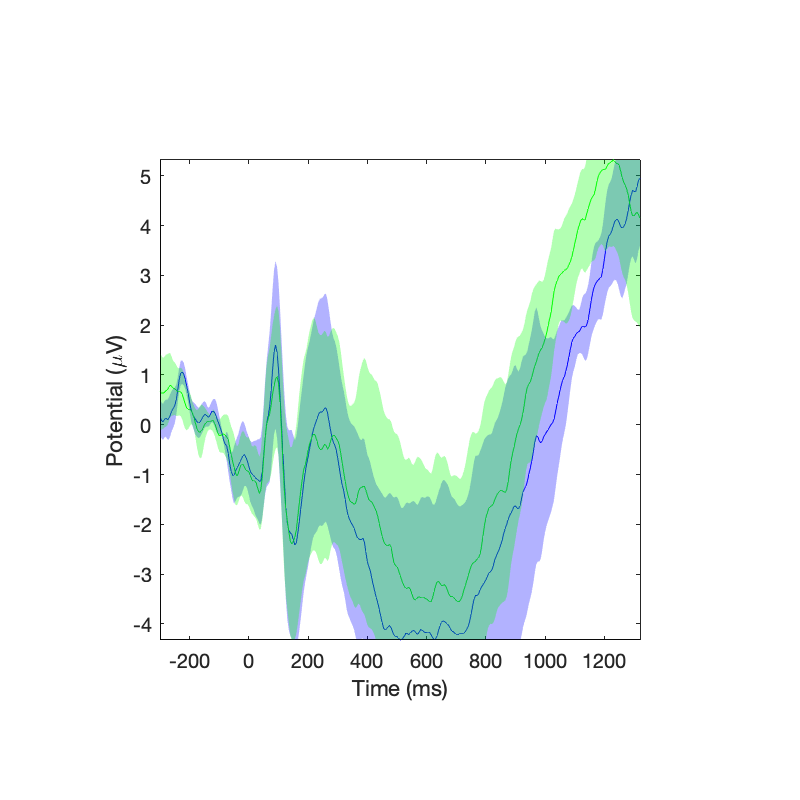

std_plotcurve(erptimes, erpdata, 'plotconditions', 'together', 'plotstderr', 'on', 'figure', 'on');

#### Plot each subject's ERP

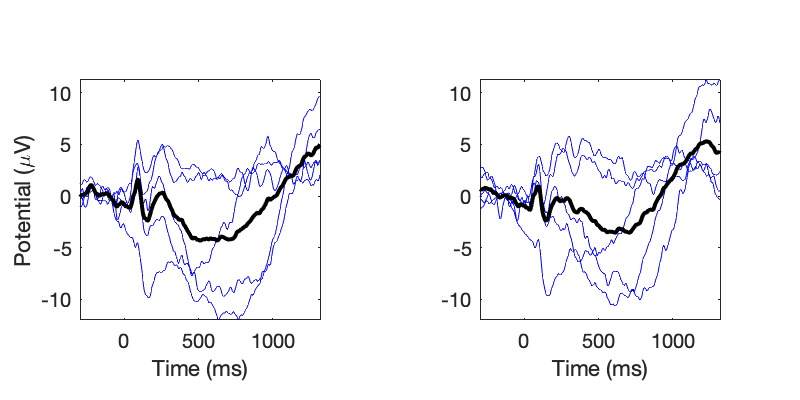

std_plotcurve(erptimes, erpdata, 'plotconditions', 'together', 'plotsubjects', 'on', 'figure', 'on');

#### **Plot the difference between two conditions**

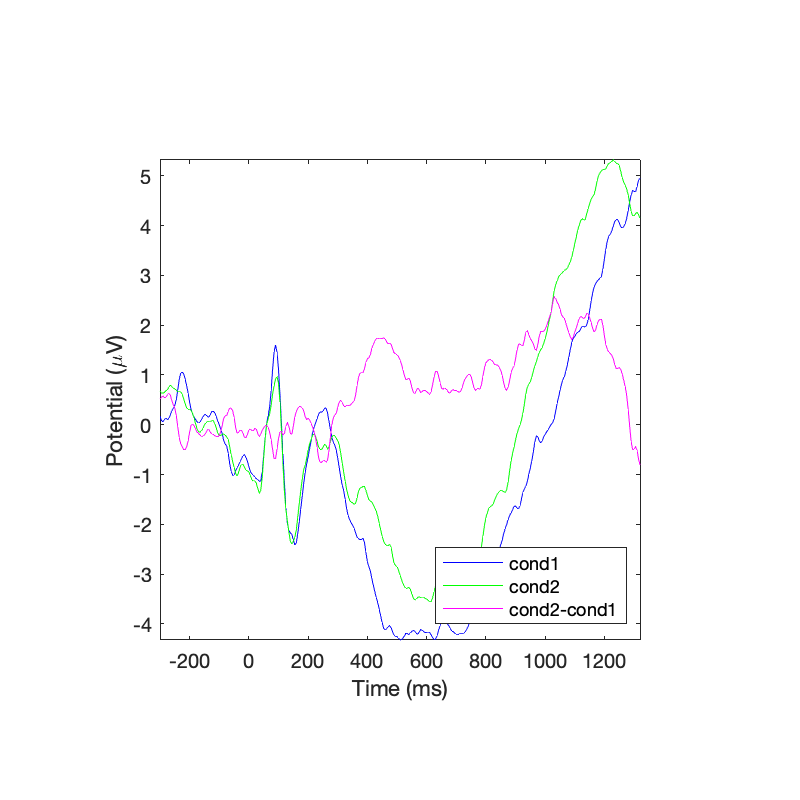

std_plotcurve(erptimes, erpdata, 'plotdiff', 'on', 'plotconditions', 'together',  'figure', 'on', 'legend', { 'cond1' 'cond2' });

#### Plot ERP topographic map

Reading subjects' data or looking up measure values in EEGLAB cache
.....
1 x 2, paired data, computing T values
Using paired t-test
Permutations (of 4000):...
Applying FDR correction for multiple comparisons


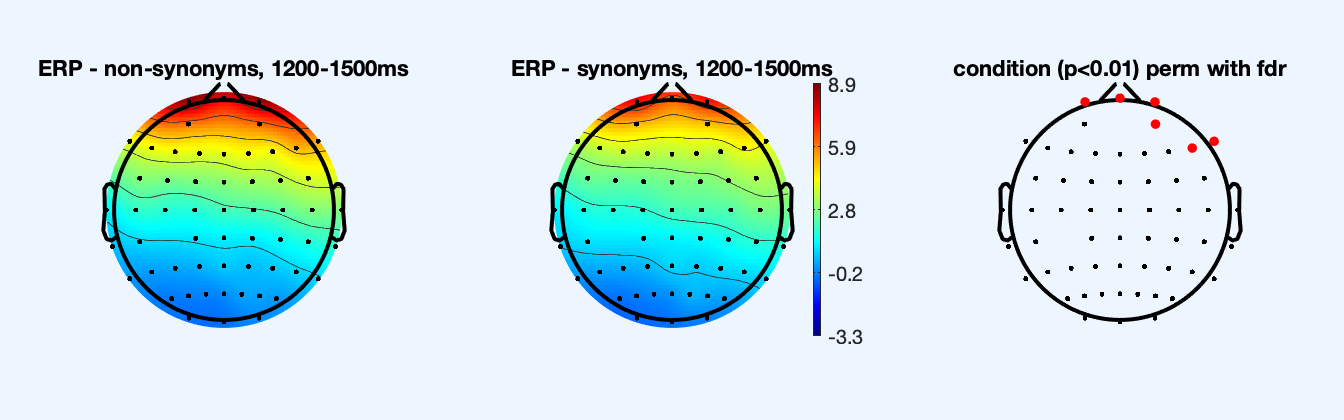

STUDY = pop_erpparams(STUDY, 'topotime',[1200 1500] ); %specify the time range to plot the topomap
STUDY = std_erpplot(STUDY,ALLEEG,'channels',{'Fp1' 'Fpz' 'Fp2' 'AF3' 'AF4' 'F7' 'F5' 'F3' 'F1' 'Fz' 'F2' 'F4' 'F6' 'F8' 'FC5' 'FC3' 'FC1' 'FCz' 'FC2' 'FC4' 'FC6' 'T7' 'C5' 'C3' 'C1' 'Cz' 'C2' 'C4' 'C6' 'T8' 'CP1' 'CPz' 'CP2' 'CP4' 'CP6' 'TP8' 'P7' 'P5' 'P3' 'P1' 'Pz' 'P2' 'P4' 'P6' 'P8' 'PO5' 'PO3' 'PO1' 'POz' 'PO2' 'PO4' 'PO6' 'O1' 'Oz' 'O2' 'LO1' 'IO1' 'SO1' 'LO2' 'TP7' 'CP5'}, 'design', 1);